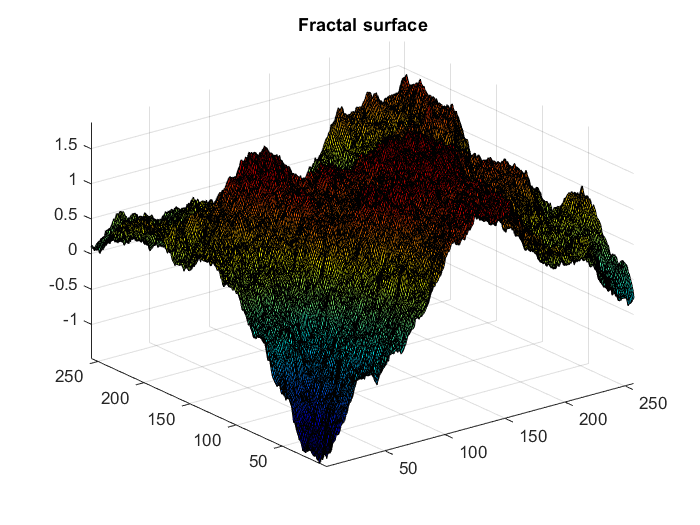

% Please run this demo file to generate three different types of urfaces
% (1) Fracal surface
% (2) Sinusoidal surface
% (3) Random surface
% If you find this toolbox useful, please cite the following papers:
% [1]	Y. Chen and H. Yang, Numerical simulation and pattern characterization of
% nonlinear spatiotemporal dynamics on fractal surfaces for the whole-heart modeling
% applications, European Physical Journal, DOI: 10.1140/epjb/e2016-60960-6
% [2]	B. Yao, F. Imani, A. Sakpal, E. W. Reutzel, and H. Yang*, �Multifractal
% analysis of image profiles for the characterization and detection of defects
% in additive manufacturing,� ASME Journal of Manufacturing Science and Engineering,
% Vol. 140, No. 3, p031014-13, 2017, DOI: 10.1115/1.4037891
% [3]	F. Imani, B. Yao, R. Chen, P. Rao, and H. Yang*, �Joint multifractal
% and lacunarity analysis of image profiles for manufacturing quality control�.
% ASME Journal Manufacturing Science and Engineering, Vol. 141, No. 4,
% p 044501-7, 2019. DOI: 10.1115/1.4042579
clear all
close all
clc

% %% Fractal surface
n=8;        % image resolution will be (2^n + 1)
H=0.7;
[row,col,G] = fractalsurface(n,H);
% % Fractal Surface Plot
ylim([-5 5])
surf(G);

title('Fractal surface');
axis tight
colormap jet

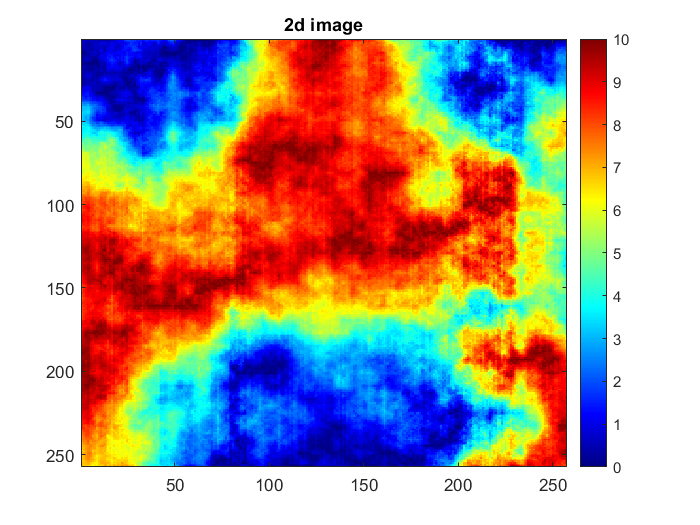

G = normalize(G, 'range',[0 10]);
clims = [min(G(:)), max(G(:))];
imagesc(G, clims);
colorbar
title('2d image')


frequency = [4 8 12];
ks = 0;
E_oil = 3;
E_air = 1;
temp = 20;
salinity = 35;
theta = 0;
variance = 0.02;
M = 1;
tmin = 0;
tmax = 10;
thickness_step = 1;

%generate reflectivity values
for i =1:1:length(frequency)
    desired_reflectivity(:, :, i) = reflectivity(frequency(i), G, ks, E_oil, E_air, temp, salinity, theta);
end



for i = 1:1:size(desired_reflectivity, 1)
    for j = 1:1:size(desired_reflectivity, 2)
            oil_found(i, j) = Detect_with_unknown_thickness(desired_reflectivity(i, j, :), M, frequency, ks, variance, E_oil, E_air, temp, salinity, theta, tmin, thickness_step, tmax);   
    end
end
















% thickness_step = 1;
%
% f = [[5 12 12]; [6 12 12]; [9 9 12]; [7 9 12]; [9 12 12]; [8 10 10]; [7 9 9]; [7 8 12]; [4 12 12]; [4 11 12]];
%
% reflectivity_values = double.empty;
% EstimationValues = double.empty;
% M =3;
% for i = 1:1:size(f, 1)
%     for j =1:1:length(f(i, :))
%         reflectivity_values(:, :, j) = reflectivity(f(i, j), G, ks, E_oil, E_air, temp, salinity, theta);
%     end
%     EstimationValues(:, :, i) = Estimate_Thickness(reflectivity_values, M, f(i, :), ks, thickness_step, variance, E_oil, E_air, temp, salinity, theta, 0, 10);
% end
%
% for i =1:1:length(frequency)
%     reflectivities(:, :, i) = reflectivity(frequency(i), G, ks, E_oil, E_air, temp, salinity, theta);
% end

% M = 5;
% tic
% y = Detection_probability(reflectivities, M, frequency, ks, variance, E_air, temp, salinity, theta);
% clims = [0, 1];
% imagesc(y, clims);
% cmp = gray;
% cmp = flipud(cmp);
% colormap(cmp);
% colorbar
% toc

% M = 50;
% tic
% Estimated_thickness = Estimate_Thickness(reflectivities, M, frequency, ks, thickness_step, variance, E_oil, E_air, temp, salinity, theta, 0 ,10);
% clims = [0, 10];
% imagesc(Estimated_thickness, clims);
% colormap jet;
% colorbar
% toc